% Dataset and descriptor foldes
DATASET_FOLDER = 'C:\Users\Alpas\OneDrive - University of Surrey\EEE3032 - Assignment\msrc_objcategimagedatabase_v2';
DESCRIPTOR_FOLDER = 'C:\Users\Alpas\OneDrive - University of Surrey\EEE3032 - Assignment\descriptors';

% Descriptor Subfolders
GLOBAL_AVERAGE_RGB_FOLDER='globalRGBaverage';
GLOBAL_RGB_HISTOGRAM_FOLDER='globalRGBhisto';
SPATIAL_GRID_FOLDER='spatialGrid';

SHOW=15; % Show top 15 results

% Pick an image at random to be the query
NIMG=length(dir(fullfile([DATASET_FOLDER,'/Images/*.bmp'])));   % number of images in collection
% queryimg=floor(rand()*NIMG);                                    % index of a random image
% queryimg = 323;
% queryimg = 152;
queryimg = 574;

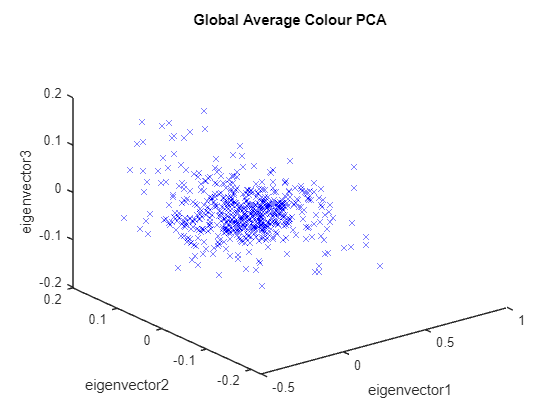

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_AVERAGE_RGB_FOLDER);

% Build eigen model
figure('Name',"Global Average Colour PCA",'NumberTitle','off')
[eigenBuild, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
title("Global Average Colour PCA");

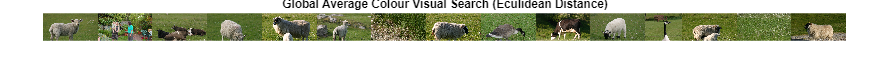

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEAT, @GetEculideanDistance);
dst=dst(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (Eculidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Average Colour Visual Search (Eculidean Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.500000, 7/14 correct out of all returned
Recall: 0.233333, 7/30 correctly returned from the dataset


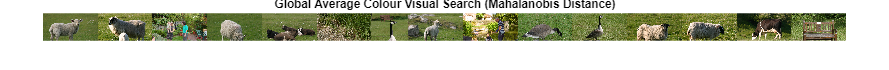

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEAT, @GetMahalanobisDistance, eigenBuild.val);
dst=dst(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Average Colour Visual Search (Mahalanobis Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.357143, 5/14 correct out of all returned
Recall: 0.166667, 5/30 correctly returned from the dataset


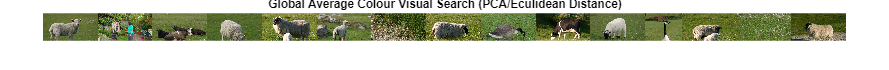

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEATPCA, @GetEculideanDistance);
dst=dst(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (PCA/Eculidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Average Colour Visual Search (PCA/Eculidean Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.500000, 7/14 correct out of all returned
Recall: 0.233333, 7/30 correctly returned from the dataset


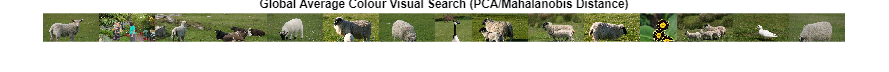

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dst(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Average Colour Visual Search (PCA/Mahalanobis Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.642857, 9/14 correct out of all returned
Recall: 0.300000, 9/30 correctly returned from the dataset


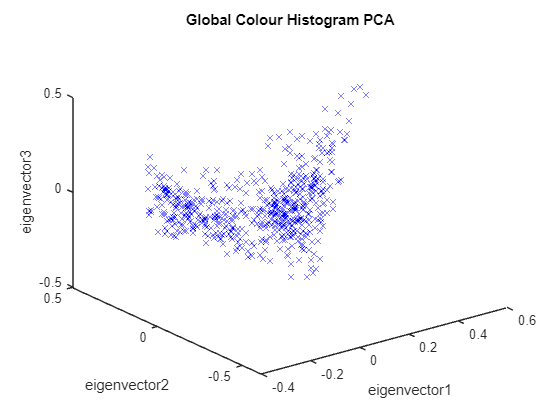

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);

% Build eigen model
figure('Name',"Global Colour Histogram PCA",'NumberTitle','off')
[eigenBuild, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
title("Global Colour Histogram PCA");

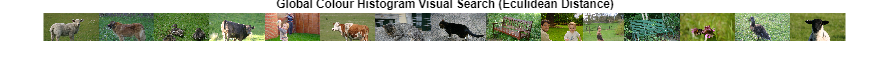

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEAT, @GetEculideanDistance);
dst=dst(1:SHOW,:);

figure('Name','Global Colour Histogram Visual Search (Eculidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Colour Histogram Visual Search (Eculidean Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.000000, 0/14 correct out of all returned
Recall: 0.000000, 0/30 correctly returned from the dataset


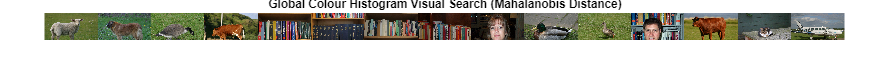

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEAT, @GetMahalanobisDistance, eigenBuild.val);
dst=dst(1:SHOW,:);

figure('Name','Global Colour Histogram Visual Search (Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Colour Histogram Visual Search (Mahalanobis Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.000000, 0/14 correct out of all returned
Recall: 0.000000, 0/30 correctly returned from the dataset


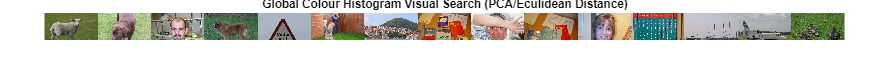

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEATPCA, @GetEculideanDistance);
dst=dst(1:SHOW,:);

figure('Name','Global Colour Histogram Visual Search (PCA/Eculidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Colour Histogram Visual Search (PCA/Eculidean Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.000000, 0/14 correct out of all returned
Recall: 0.000000, 0/30 correctly returned from the dataset


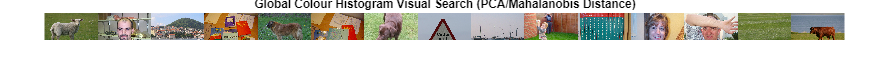

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dst(1:SHOW,:);

figure('Name','Global Colour Histogram Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Global Colour Histogram Visual Search (PCA/Mahalanobis Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.000000, 0/14 correct out of all returned
Recall: 0.000000, 0/30 correctly returned from the dataset


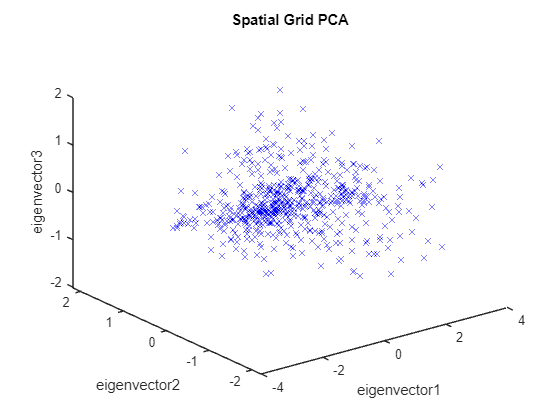

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, SPATIAL_GRID_FOLDER);

% Build eigen model
figure('Name',"Spatial Grid PCA",'NumberTitle','off')
[eigenBuild, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
title("Spatial Grid PCA");

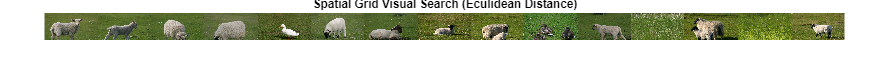

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEAT, @GetEculideanDistance);
dst=dst(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (Eculidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Spatial Grid Visual Search (Eculidean Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.571429, 8/14 correct out of all returned
Recall: 0.266667, 8/30 correctly returned from the dataset


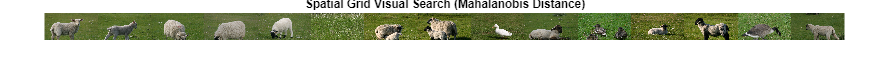

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEAT, @GetMahalanobisDistance, eigenBuild.val);
dst=dst(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Spatial Grid Visual Search (Mahalanobis Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.642857, 9/14 correct out of all returned
Recall: 0.300000, 9/30 correctly returned from the dataset


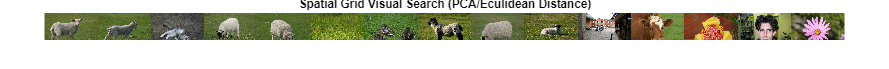

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEATPCA, @GetEculideanDistance);
dst=dst(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (PCA/Eculidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Spatial Grid Visual Search (PCA/Eculidean Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.357143, 5/14 correct out of all returned
Recall: 0.166667, 5/30 correctly returned from the dataset


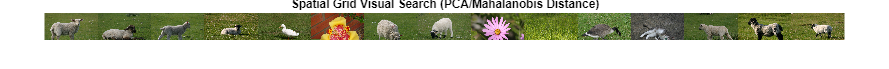

% Get distance between query and candidate images
dst = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dst(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES));
axis off;
title("Spatial Grid Visual Search (PCA/Mahalanobis Distance)");

% Calculate Precision and Recall
PrecisionRecall(allfiles, NIMG, dst, SHOW);

Precision: 0.428571, 6/14 correct out of all returned
Recall: 0.200000, 6/30 correctly returned from the dataset


%Overall Evaluation


function outdisplay = GenerateVisualSearchDisplay(dst, ALLFILES)
    outdisplay=[];
    for i=1:size(dst,1)
        img=imread(ALLFILES{dst(i,2)});
        img=img(1:2:end,1:2:end,:); % make image a quarter size
        img=img(1:81,:,:); % crop image to uniform size vertically (some MSVC images are different heights)
        outdisplay=[outdisplay img];
    end
end